clc
clear all

%Discover Analog Input Devices
d = daqlist("ni")

d = 1×4 table
    DeviceID                       Description                                Model                   DeviceInfo      
    ________    _________________________________________________    ________________________    _____________________

     "Dev1"     "National Instruments(TM) USB-6356 (32 MS) (BNC)"    "USB-6356 (32 MS) (BNC)"    1×1 daq.ni.DeviceInfo



dq = daq("ni");

dq.Rate = 1000000;
addinput(dq, "Dev1", "ai0", "Voltage");
addinput(dq, "Dev1", "ai1", "Voltage");
addinput(dq, "Dev1", "ai2", "Voltage");
addinput(dq, "Dev1", "ai3", "Voltage");

%Aquire image through Webcam
webcamlist

ans = 2×1 cell array
    {'MD35'        }
    {'UTP200X003MP'}


cam = webcam(2)

cam =   webcam with properties:

                     Name: 'UTP200X003MP'
     AvailableResolutions: {'640x480'  '320x240'  '160x120'}
               Resolution: '640x480'
             WhiteBalance: 4000
                      Hue: 0
               Brightness: 0
               Saturation: 32
         WhiteBalanceMode: 'auto'
                    Gamma: 100
             ExposureMode: 'auto'
    BacklightCompensation: 0
                 Exposure: -5
                 Contrast: 32
                Sharpness: 1


Trial records here

t =   DigitalTrigger with properties:

         Source: 'External'
    Destination: 'Dev1/PFI8'
           Type: StartTrigger
      Condition: 'RisingEdge'


SpinCheck = 3.0305

SpinCheck = 3.0323

SpinCheck = 3.0184

SpinCheck = 3.0118

SpinCheck = 3.0209

SpinCheck = 3.0136

SpinCheck = 2.9938

SpinCheck = 2.9955

SpinCheck = 2.9879

SpinCheck = 2.9948

SpinCheck = 2.8054

SpinCheck = 2.8927

SpinCheck = 2.9177

SpinCheck = 2.7636

SpinCheck = 2.7116

SpinCheck = 3.0094

SpinCheck = 3.0141

SpinCheck = 3.0157

SpinCheck = 3.0065

SpinCheck = 3.0026

SpinCheck = 3.0035

SpinCheck = 2.9941

SpinCheck = 2.9963

SpinCheck = 2.6703

SpinCheck = 2.3916

SpinCheck = 3.5849

SpinCheck = 5.0157

T = 33.0040

t =   DigitalTrigger with properties:

         Source: 'External'
    Destination: 'Dev1/PFI8'
           Type: StartTrigger
      Condition: 'RisingEdge'


SpinCheck = 3.0104

SpinCheck = 3.0202

SpinCheck = 3.0076

SpinCheck = 3.0030

SpinCheck = 3.0016

SpinCheck = 3.0044

SpinCheck = 2.8801

SpinCheck = 2.9958

SpinCheck = 2.9946

SpinCheck = 2.9944

SpinCheck = 2.9958

SpinCheck = 2.7265

SpinCheck = 2.7140

SpinCheck = 2.7729

SpinCheck = 2.6430

SpinCheck = 2.3639

SpinCheck = 3.0038

SpinCheck = 3.0050

SpinCheck = 2.9980

SpinCheck = 3.0075

SpinCheck = 2.6445

SpinCheck = 2.6551

SpinCheck = 2.9944

SpinCheck = 2.9909

SpinCheck = 2.9885

SpinCheck = 2.9926

SpinCheck = 2.9951

SpinCheck = 2.9873

SpinCheck = 2.9933

SpinCheck = 2.9888

SpinCheck = 2.9857

SpinCheck = 2.9854

SpinCheck = 2.9924

SpinCheck = 2.9949

SpinCheck = 2.9920

SpinCheck = 2.9914

SpinCheck = 2.6562

SpinCheck = 2.2879

SpinCheck = 2.4834

SpinCheck = 2.9075

SpinCheck = 2.2681

SpinCheck = 2.4401

SpinCheck = 2.4720

SpinCheck = 2.9990

SpinCheck = 2.8877

SpinCheck = 2.7145

SpinCheck = 2.9863

SpinCheck = 2.6145

SpinCheck = 2.6982

SpinCheck = 2.4092

SpinCheck = 2.9347

SpinCheck = 2.7979

SpinCheck = 2.5432

SpinCheck = 2.9824

SpinCheck = 2.9852

SpinCheck = 2.2926

SpinCheck = 2.3944

SpinCheck = 3.9311

SpinCheck = 5.0154

T =    33.0040   46.0623


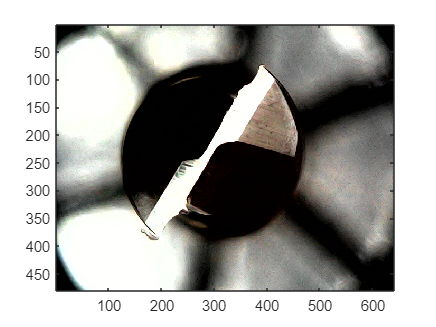

for i = 1:2 %number of trial
    %Physically connect the switch to terminal PFI8 on NI USB-6356
    t = addtrigger(dq,"Digital","StartTrigger","External","Dev1/PFI8")
    t.Condition = 'FallingEdge';
    dq.DigitalTriggerTimeout = 30;

    dataIn = read(dq, seconds(24));
    tStart = tic;
    removetrigger(dq,"Digital",1);
    addinput(dq, "Dev1", "ai4", "Voltage");

    %pause(2);
    Spindata = read(dq,seconds(0.25));
    TriggerOut = Spindata(:,5);
    TriggerOut = transpose(table2array(TriggerOut));
    SpinCheck = mean(TriggerOut)

    while SpinCheck > 0.2 && SpinCheck < 4.8
        Spindata = read(dq, seconds(0.25));
        TriggerOut = Spindata(:,5);
        TriggerOut = transpose(table2array(TriggerOut));
        SpinCheck = mean(TriggerOut)
    end
    T(i) = toc(tStart) +24-3.9
    %plunge time 4.11s
    %104.39 /104.15 /104 / 104.71
    pause(7);
    
    img = snapshot(cam);
    %use the image function to display the acquired image
    image(img)

    dataname = fullfile(sprintf('T9DC%d.mat', i+94));
    imagename = fullfile(sprintf('T9DC%dTool.png', i+94));
    imwrite(img,imagename)
    save(dataname, 'dataIn');

    clear Spindata dataIn img
    removechannel(dq,5)
end

%img = snapshot(cam);
%imwrite(img,"T1New4.png")
%G20G90G0X-3.23Z1.1